clc;
clear;
close all;


t = [0:0.01:100];


s = tf('s');


% Datos de la plata
Kp = 0.9058;
L = 0.11419;
T = 1.2637; 
a = 0;      
tao = L/T 

tao = 0.0904


P = (Kp*exp(-L*s))/(1+T*s)

P =
 
                    0.9058
  exp(-0.114*s) * -----------
                  1.264 s + 1
 
Continuous-time transfer function.





% Controlador Murril
Kc = (0.928/Kp)*(L/T)^(0.946)

Kc = 0.1054

Ti = (T/1.078)*(L/T)^(0.583)

Ti = 0.2886

C = Kc* (( Ti*s + 1)/(Ti*s))

C =
 
  0.03043 s + 0.1054
  ------------------
       0.2886 s
 
Continuous-time transfer function.



L = P*C

L =
 
                   0.02756 s + 0.09548
  exp(-0.114*s) * ---------------------
                  0.3648 s^2 + 0.2886 s
 
Continuous-time transfer function.





% Servocontrol
Myr = ( C * P ) /(1+ C * P );
% Regulador
Myd = minreal( P /(1+ C * P ) ); 

1 state removed.


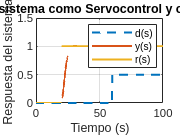


r = 0; %referencia
r ( t >= 20) = 1;

% La perturbacipón pasa de 0 a 0.5 cuando el tiempo es mayor o igual a 70.
d = 0; %perturbacion
d ( t >= 60) = 0.5;

% Para simular el servocontrol
yr = lsim ( Myr , r , t );
% Para simular el regulador
yd = lsim ( Myd , d , t );
y = yr + yd;
y1= yr;

figure (1) ;
plot (t,d,'--',t,y,t,r, LineWidth = 1.5)
hold on;
title ('Respuesta del sistema como Servocontrol y como Regulador PI') ;
xlabel ('Tiempo (s)') ;
ylabel ('Respuesta del sistema ') ;
legend ('d(s)','y(s)','r(s)') %leyenda
grid on;
hold off;




% Murril 
sisotool(C)
bode(L)
margin(L)
grid on


ind = find(y1>max(y1)-0.02*(max(y1)),1);
ta2 = t(ind) - 20 %se resta el -1 del escalon

ta2 = 7.8900



% Sobrepaso máximo no normalizado
[Ymax1, indymax1] = max(y1,[],'all')

Ymax1 = 1.0111

indymax1 = 3051


% Máximo de la señal realimentada 
Ymax = max(abs(max(r)),abs(min(r)))

Ymax = 1


% Sobrepaso máximo normalizado
Mpnr = 100*(Ymax1-Ymax)/(Ymax)

Mpnr = 1.1088